# Waxtop

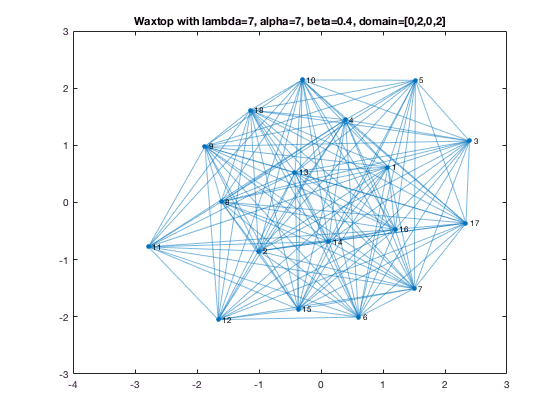

lambda=7;
alpha=7;
beta=0.4;
x_min=0;
x_max=2;
y_min=0;
y_max=2;
domain=[x_min x_max y_min y_max];

G=waxtop(lambda, alpha, beta, domain);
tit= sprintf('Waxtop with lambda=%d, alpha=%d, beta=%0.1f, domain=[%d,%d,%d,%d]',lambda, alpha, beta, domain);
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
plot(G);
N=7;
title(tit);
print(fig,[tit '.png'],'-dpng');

## Unknown topology edge disjoint normal 

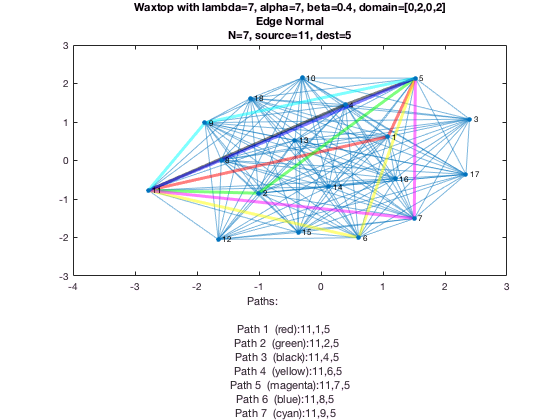

source=11;
dest=5;
ordest=sprintf('N=%d, source=%d, dest=%d',N,source,dest);
paths=disjoint('other', 'edges', source, dest, N, G,false, false);
tit1=[tit,'-edge-normal'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plot(G);
plotPaths(p, paths);
title({tit;'Edge Normal';ordest});
xlabel(stringPaths(paths));
print(fig,[tit1 '.png'],'-dpng');

## Unknown topology edge disjoint max 

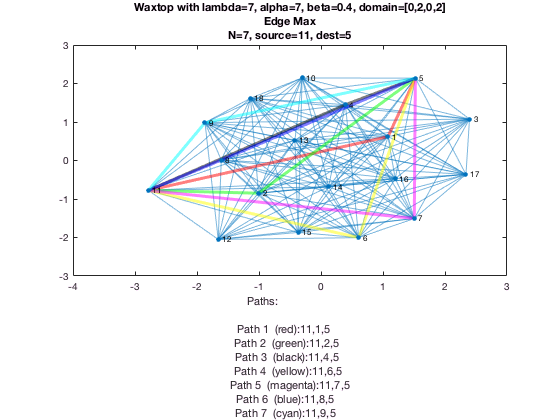

paths=disjoint('other', 'edges', source, dest, N, G,false, true);
tit1=[tit,'-edge-max'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plot(G);
plotPaths(p, paths);
title({tit;'Edge Max';ordest});
xlabel(stringPaths(paths));
print(fig,[tit1 '.png'],'-dpng');

## Unknown topology node disjoint normal 

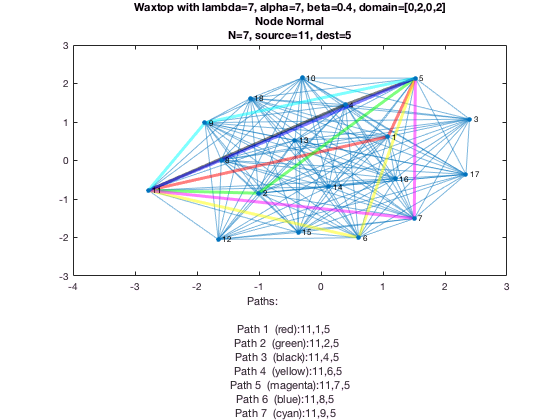

paths=disjoint('other', 'nodes', source, dest, N, G,false, false);
tit1=[tit,'-node-normal'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plot(G);
plotPaths(p, paths);
title({tit;'Node Normal';ordest});
xlabel(stringPaths(paths));
print(fig,[tit1 '.png'],'-dpng');

## Unknown topology node disjoint max

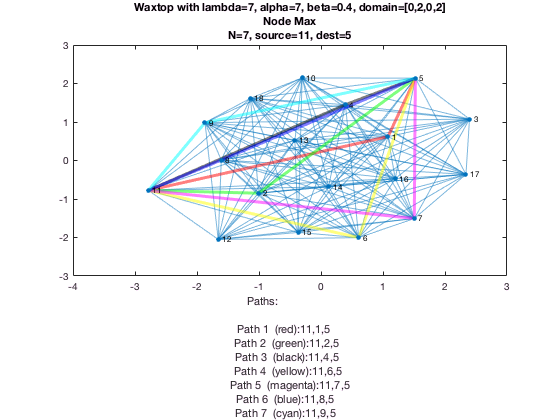

paths=disjoint('other', 'nodes', source, dest, N, G,false, true);
tit1=[tit,'-node-max'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plot(G);
plotPaths(p, paths);
title({tit;'Node Max';ordest});
xlabel(stringPaths(paths));
print(fig,[tit1 '.png'],'-dpng');

# RandGraphs

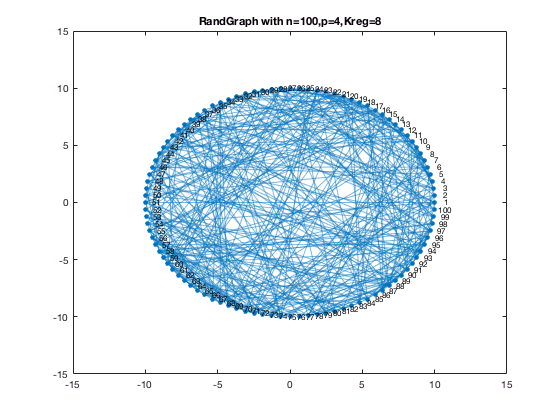

nv=100;
pb=4;
Kreg=8;
G=erdosRenyi(nv,pb,Kreg);
tit= sprintf('RandGraph with n=%d,p=%d,Kreg=%d',nv,pb,Kreg);
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
p=plot(G,'XData',G.Nodes.Xpoint,'YData',G.Nodes.Ypoint);
N=7;
title(tit);
print(fig,[tit '.png'],'-dpng');

## Unknown topology edge disjoint normal 

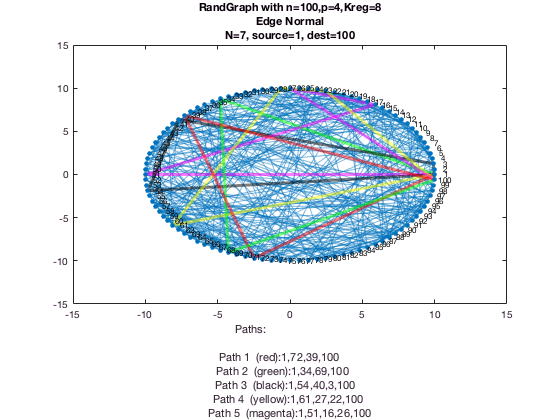

source=1;
dest=100;
ordest=sprintf('N=%d, source=%d, dest=%d',N,source,dest);
paths=disjoint('other', 'edges', source, dest, N, G,false, false);
tit1=[tit,'-edge-normal'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plot(G,'XData',G.Nodes.Xpoint,'YData',G.Nodes.Ypoint);
plotPaths(p, paths);
title({tit;'Edge Normal';ordest});
xlabel(stringPaths(paths));
print(fig,[tit1 '.png'],'-dpng');

## Unknown topology edge disjoint max 

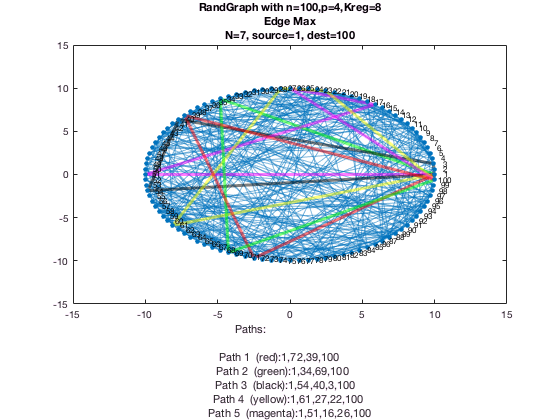

paths=disjoint('other', 'edges', source, dest, N, G,false, true);
tit1=[tit,'-edge-max'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plot(G,'XData',G.Nodes.Xpoint,'YData',G.Nodes.Ypoint);
plotPaths(p, paths);
title({tit;'Edge Max';ordest});
xlabel(stringPaths(paths));
print(fig,[tit1 '.png'],'-dpng');

## Unknown topology node disjoint normal 

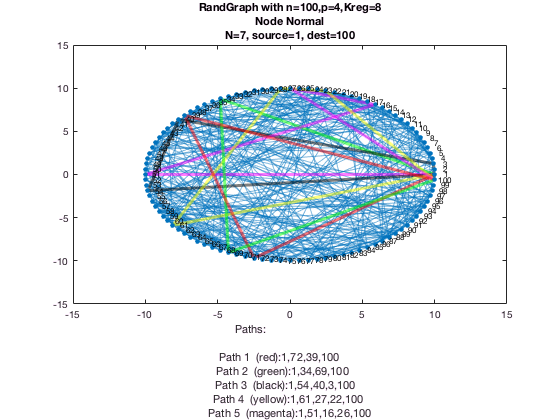

paths=disjoint('other', 'nodes', source, dest, N, G,false, false);
tit1=[tit,'-node-normal'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plot(G,'XData',G.Nodes.Xpoint,'YData',G.Nodes.Ypoint);
plotPaths(p, paths);
title({tit;'Node Normal';ordest});
xlabel(stringPaths(paths));
print(fig,[tit1 '.png'],'-dpng');

## Unknown topology node disjoint max

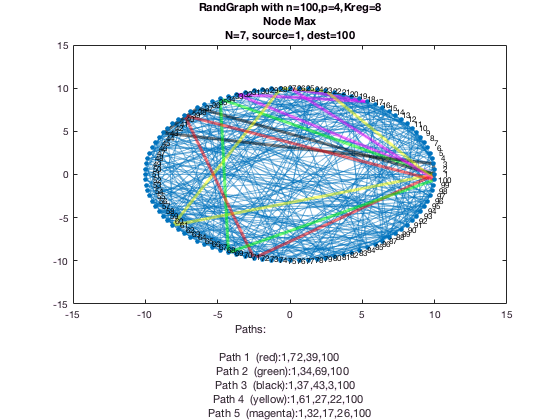

paths=disjoint('other', 'nodes', source, dest, N, G,false, true);
tit1=[tit,'-node-max'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plot(G,'XData',G.Nodes.Xpoint,'YData',G.Nodes.Ypoint);
plotPaths(p, paths);
title({tit;'Node Max';ordest});
xlabel(stringPaths(paths));
print(fig,[tit1 '.png'],'-dpng');